# J1リーグ得点数の分布

clear;
clc;
close all;

Jリーグの試合データの読み込み

tbl_result=readtable('../data/JLeagueResults.xlsx');
tbl_result.Category=categorical(tbl_result.Category);

ここ5年程度のJ1リーグのみ抽出

ind = tbl_result.Year<=2023 & tbl_result.Year>=2019 ...
    & tbl_result.Category=='Ｊ１';
tbl_result=tbl_result(ind,:);

ゴール数の平均と分散

goals=[tbl_result.HomeGoals;tbl_result.AwayGoals];
muGoals=mean(goals)

muGoals = 1.2877

sigmaGoals=var(goals)

sigmaGoals = 1.4192

相対頻度を算出して図示

hCounts=histcounts(goals,0:max(goals)+1)

hCounts =          925        1133         682         309         105          41          11           0           2


y=hCounts./sum(hCounts)

y =     0.2883    0.3532    0.2126    0.0963    0.0327    0.0128    0.0034         0    0.0006


bins=0:max(goals)

bins =      0     1     2     3     4     5     6     7     8


figure
bar(bins,y);set(gca,'fontname','メイリオ');
hold on;grid on;
title('ゴール数分布 (J1リーグ　2019-2023)')
xlabel('ゴール数')
ylabel('相対頻度')

同じ平均を持つポアソン分布を重ねる

p=poisspdf(bins,muGoals)

p =     0.2759    0.3553    0.2288    0.0982    0.0316    0.0081    0.0017    0.0003    0.0001


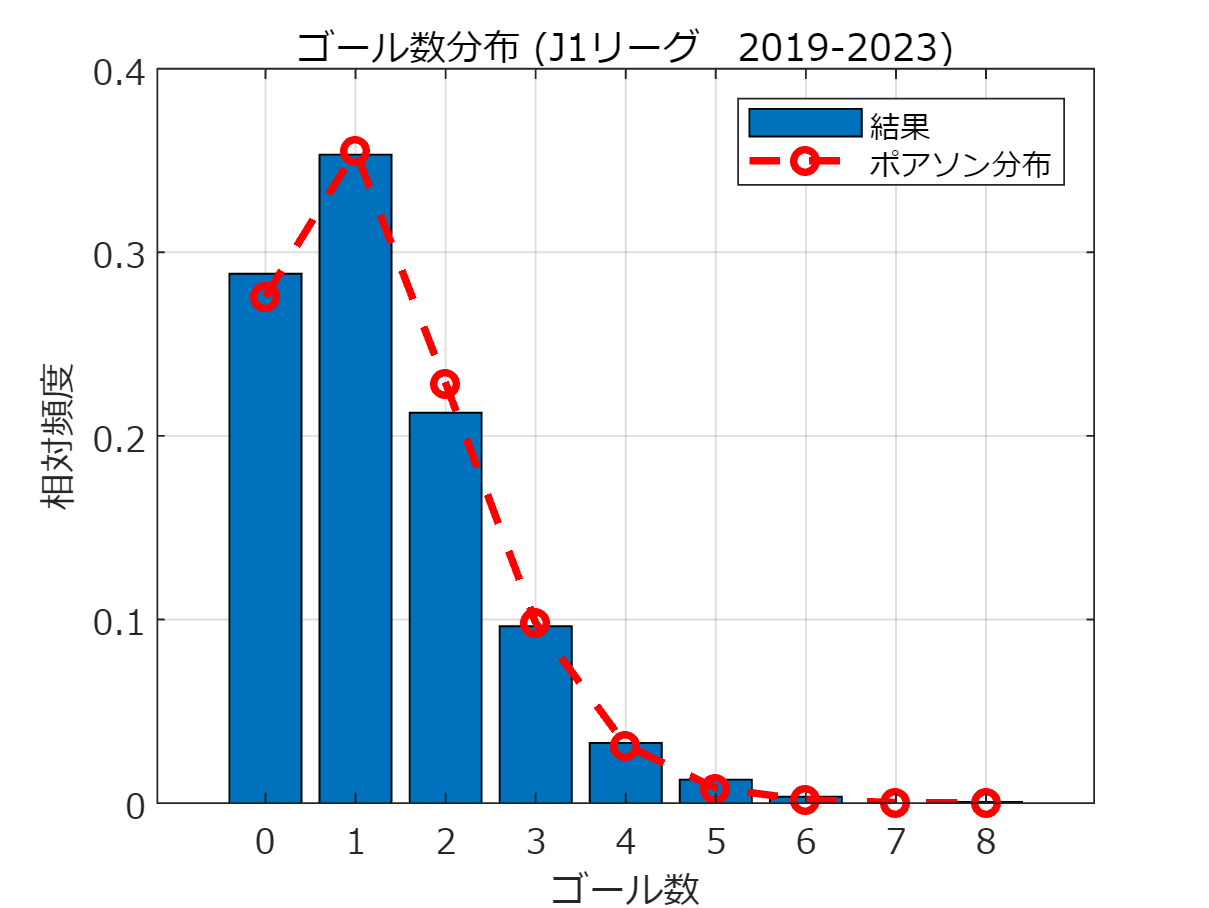

plot(bins, p, 'ro--','LineWidth',2)
legend({'結果','ポアソン分布'})
exportgraphics(gcf,'fig_J1GoalDistribution.pdf');